### Reading a video file

Let us read a frame from a gray-level video. We use the readFrame function

%% Reads and shows a frame frome a gray-level video

sequenceName = 'foreman'; 
resolution = 'cif'; 
colorspace = 'y';
fileName = [sequenceName '_' resolution '.' colorspace];
k = 3;

% uses the function readFrame to read a single image
grayFrame = readFrame(fileName, k);
whos grayFrame % this command shows the characteristic of this variable

  Name             Size              Bytes  Class     Attributes

  grayFrame      288x352            811008  double              



The readFrame functions returns a double. Let us display the image

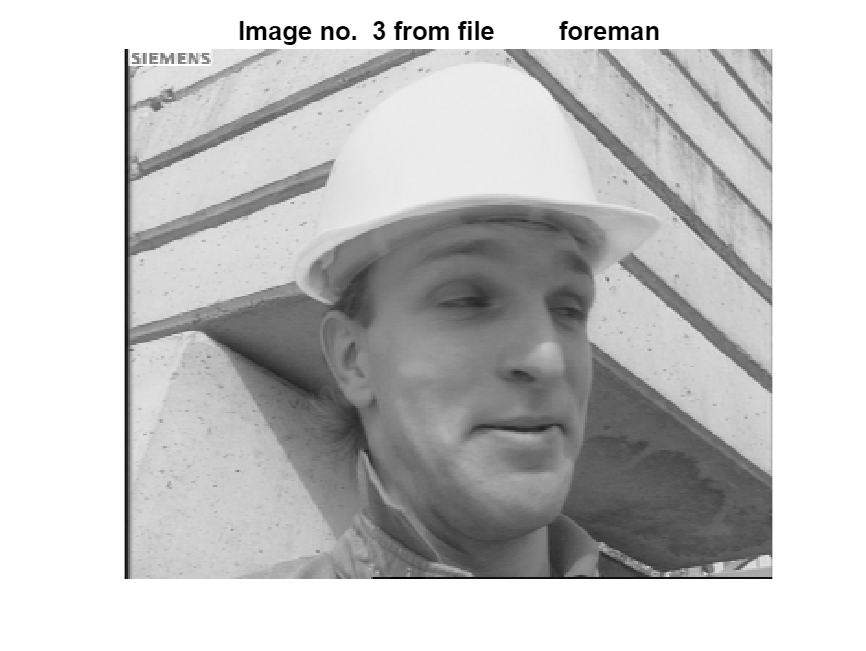

% image display 
figure; %create a window for a figure 
image(uint8(grayFrame)); % draw the image. UINT8 is needed for range 0-255
colormap(gray(256)); % colormap tells that 0 is black --> 255 is white
axis image; axis off; % proportional axis, ticks are hidden
title(sprintf('Image no. %2d from file %15s',k, sequenceName)); %make title 

Now an example of video processing: we compute the difference between consecutive images of the input video

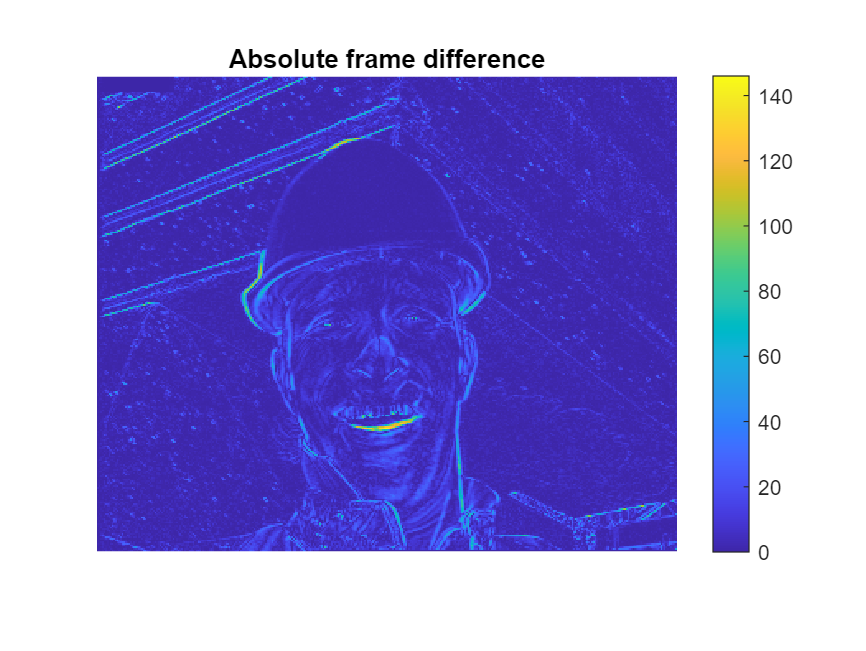

%% Simple video processing example
k=30;

% Show frame difference
sequenceName = 'foreman'; 
resolution = 'cif'; 
colorspace = 'y';
fileName = [sequenceName '_' resolution '.' colorspace];

frame1 = readFrame(fileName, k  );
frame2 = readFrame(fileName, k+1);
absImmDiff = abs(frame1-frame2); % an "error" image 
figure; imagesc(absImmDiff); axis image; axis off
colorbar; % It shows the correspondence between colors and values
title('Absolute frame difference');

Let us now load a color image

Let us read a frame from a gray-level video. We use the readFrame function

%% Reads and shows a frame frome a gray-level video

sequenceName = 'foreman'; 
resolution = 'cif'; 
colorspace = 'yuv';
fileName = [sequenceName '_' resolution '.' colorspace];
k = 20;

% uses the function readFrame to read a single image
colorFrame = readFrame(fileName, k);
whos colorFrame % this command shows the characteristic of this variable

  Name              Size                 Bytes  Class     Attributes

  colorFrame      288x352x3            2433024  double              



Display the image

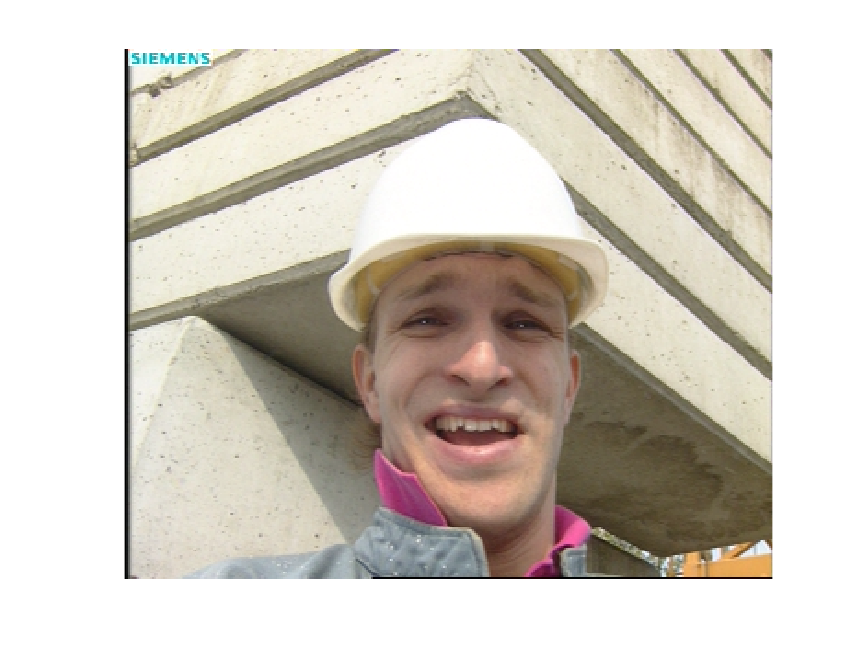

image(ycbcr2rgb(uint8(colorFrame))); axis image; axis off